# **Robust Control with Nominal Mixed-Sensitivity Design**

### Dataset Upload

clc; clear all; close all

L_nom = 36.5e-6;
Lm_nom = 0.99*L_nom/sqrt(2.33);
C_nom = 100e-06;


load("dataset\20_30.mat"); C1 = C; k1 = k; Lm1 = k1*L_nom/sqrt(2.33);
load("dataset\25_35.mat"); C2 = C; k2 = k; Lm2 = k2*L_nom/sqrt(2.33);
load("dataset\30_35_40.mat"); C3 = C; k3 = k; Lm3 = k3*L_nom/sqrt(2.33);
load("dataset\45_50_60.mat"); C4 = C; k4 = k; Lm4 = k4*L_nom/sqrt(2.33);

Lm_bm = mean([Lm1, Lm2, Lm3, Lm4]);
C_bm = mean([C1, C2, C3, C4]);

fprintf('Variation to Real Value\n Lm: %0.3f %%\t C: %0.3f %%', (1-Lm_bm/Lm_nom)*100, (1-C_bm/C_nom)*100);

Variation to Real Value
 Lm: 33.533 %	 C: -19.428 %

### System Definition

DuCy=50; 
I_Lo=0; V_Co=0;
Vg=5; Vd=0;
Vs=[Vg Vd];
X=[I_Lo V_Co];


[~,~,~,~,Gnom] =flyback_ss(Vs,X,DuCy,Lm_bm,C_bm);
[~,~,~,~,G1] =flyback_ss(Vs,X,DuCy,Lm1,C1);
[~,~,~,~,G2] =flyback_ss(Vs,X,DuCy,Lm2,C2);
[~,~,~,~,G3] =flyback_ss(Vs,X,DuCy,Lm3,C3);
[~,~,~,~,G4] =flyback_ss(Vs,X,DuCy,Lm4,C4);

**Modeling Plant Variability as Uncertainty**

To apply robust control tools, we can replace this set of models with a single uncertain plant model whose range of behaviors includes `p1` through `p6`. This is one use of the command `ucover`. This command takes an array of LTI models `Parray` and a nominal model `Pnom` and models the difference `Parray-Pnom` as multiplicative uncertainty in the system dynamics.

Because `ucover` expects an array of models, use the `stack` command to gather the plant models `p1` through `p6` into one array.

Garray = stack(1,G1,G2,G3,G4);

Next, use `ucover` to "cover" the range of behaviors `Parray` with an uncertain model of the form

`P = Pnom * (1 + Wt * Delta)`

where all uncertainty is concentrated in the "unmodeled dynamics" `Delta` (a `ultidyn` object). Because the gain of `Delta` is uniformly bounded by 1 at all frequencies, a "shaping" filter `Wt` is used to capture how the relative amount of uncertainty varies with frequency. This filter is also referred to as the uncertainty weighting function.

Try a 4th-order filter `Wt` for this example:

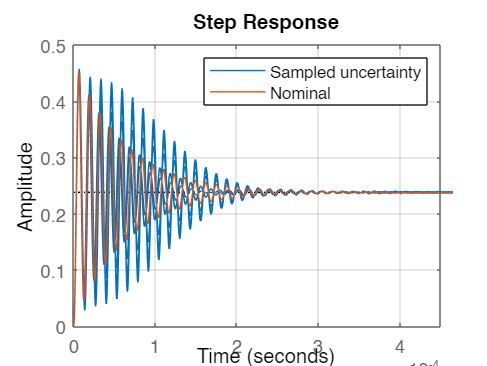

orderWt = 4;
[Gunc,Info] = ucover(Garray,Gnom,orderWt,'InputMult');
step(Gunc,getNominal(Gunc))
grid on
legend('Sampled uncertainty','Nominal')

Mixed-sensitivity loop shaping lets you design an *H*∞ controller by simultaneously shaping the frequency responses for tracking and disturbance rejection, noise reduction and robustness, and controller effort. This technique is a useful way to balance the necessary tradeoff between performance and robustness (see [Loop Shaping for Performance and Robustness](https://it.mathworks.com/help/robust/gs/loop-shaping-for-performance-and-robustness.html)). To use this technique, you convert your desired responses into up to three weighting functions that the [`mixsyn`](https://it.mathworks.com/help/robust/ref/dynamicsystem.mixsyn.html) command uses to synthesize the controller.

**Problem Setup**

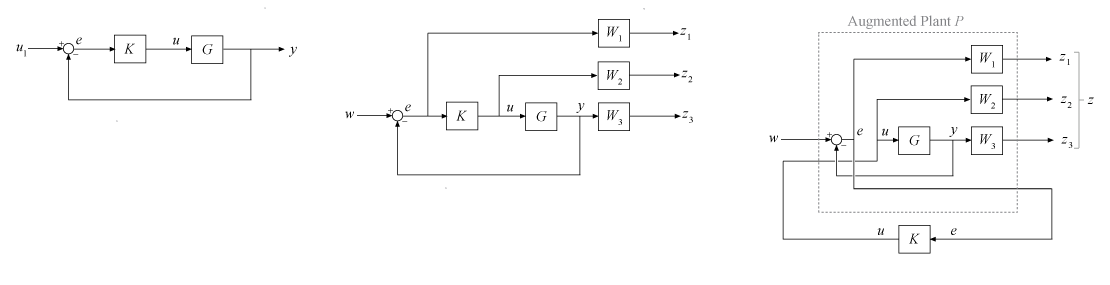

- `mixsyn` designs a controller *K* for your plant *G*, assuming the standard control configuration of the following diagram.

- To do so, the function appends the weighting functions you provide, *W*1(*s*), *W*2(*s*), and *W*3(*s*), to the control system, as shown in the following diagram.

- `mixsyn` treats the problem as an *H*∞ synthesis problem (see [`hinfsyn`](https://it.mathworks.com/help/robust/ref/dynamicsystem.hinfsyn.html)). It analyzes the weighted control system as *LFT*(*P*,*K*), where *P* is an augmented plant *P* such that {*z*;*e*} = *P*{*w*;*u*}, as shown in the following diagram.

The transfer function from *w* to *z* can be expressed as

*M*(*s*)= $\left\lbrack \begin{array}{c}
W_1 S\\
W_2 \textrm{KS}\\
W_3 T
\end{array}\right\rbrack$,

where

- *S* = (*I* + *GK*)–1 is the sensitivity function.

- *KS* is the transfer function from *w* to *u* (the control effort).

- *T* = (*I* – *S*) = *GK*(*I* + *GK*)–1 is the complementary sensitivity function.

`mixsyn` seeks a controller *K* that minimizes ||*M*(*s*)||∞, the *H*∞ norm (peak gain) of *M*. To do so, it invokes `hinfsyn` on the augmented plant `P = augw(G,W1,W2,W3)`.

**Choose Weighting Functions**

For loop gain *L* = *GK*, to achieve good reference tracking and disturbance rejection, you typically want high loop gain at low frequency. To achieve robustness and attenuation of measurement noise, you typically want *L* to roll off at high frequency. This loop shape is equivalent to small *S* at low frequency and small *T* at high frequency.

For mixed-sensitivity loop shaping, you choose weighting functions to specify those target shapes for *S* and *T* as well as the control effort *KS*. The *H*∞ design constraint,


$${\left\|M\left(s\right)\right\|}_{\infty } =\left\|\left\lbrack \begin{array}{c}
W_1 S\\
W_2 \textrm{KS}\\
W_3 T
\end{array}\right\rbrack \right\|\le 1$$


means that

- 
$${\left\|S\right\|}_{\infty } \le \left|W_1^{-1} \right|$$


- 
$${\left\|\textrm{KS}\right\|}_{\infty } \le \left|W_2^{-1} \right|$$


- 
$${\left\|T\right\|}_{\infty } \le \left|W_3^{-1} \right|$$


Therefore, you set the weights equal to the reciprocals of the desired shapes for *S*, *KS*, and *T*. In particular,

- For good reference-tracking and disturbance-rejection performance, choose *W*1 large inside the control bandwidth to obtain small *S*.

- For robustness and noise attenuation, choose *W*3 large outside the control bandwidth to obtain small *T*.

- To limit control effort in a particular frequency band, increase the magnitude of *W*2 in this frequency band to obtain small *KS*.

`mixsyn` returns the minimum ||*M*(*s*)||∞ in the output argument `gamma`. For the returned controller *K*, then,


$${\left\|S\right\|}_{\infty } \le \gamma \;\left|W_1^{-1} \right|$$



$${\left\|\textrm{KS}\right\|}_{\infty } \le \gamma \left|W_2^{-1} \right|$$



$${\left\|T\right\|}_{\infty } \le \gamma \left|W_3^{-1} \right|$$


You can relate ‖*T*‖∞ and ‖*S*‖∞ to the classical gain margin *GM* and phase margin *θ* in each feedback loop of the multivariable feedback system illustrated in the previous section, via the formulas: 

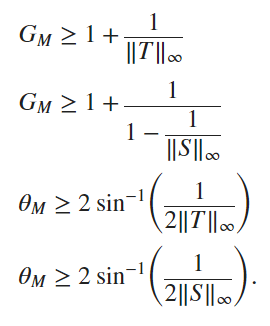

**Nominal Mixed-Sensitivity Design**

Start with a basic mixed-sensitivity design using [`mixsyn`](https://it.mathworks.com/help/robust/ref/dynamicsystem.mixsyn.html). Pick the weights to achieve good performance while limiting bandwidth and control effort. (See [Mixed-Sensitivity Loop Shaping](https://it.mathworks.com/help/robust/gs/using-mixsyn-for-h-infinity-loop-shaping.html) for details about this technique and how to choose weighting functions.)

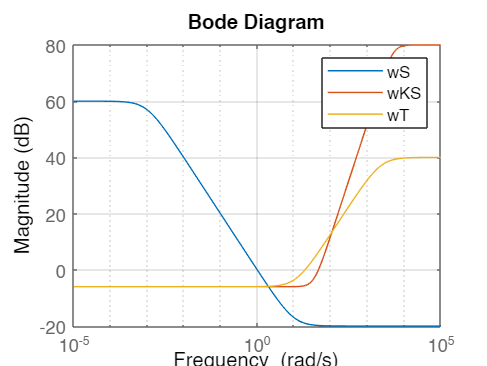

wS = makeweight(1e3,1,1e-1);
wKS = makeweight(0.5,[500 1e2],1e4,0,2);
wT = makeweight(0.5,20,100);

bodemag(wS,wKS,wT), grid
legend('wS','wKS','wT')

Gamma needs to be below 1 so that the closed-loop system meets the design requirements.

[K1,~,gam] = mixsyn(Gnom,wS,wKS,wT);
gam

gam = 2.1736

Close the feedback loop and plot the step response

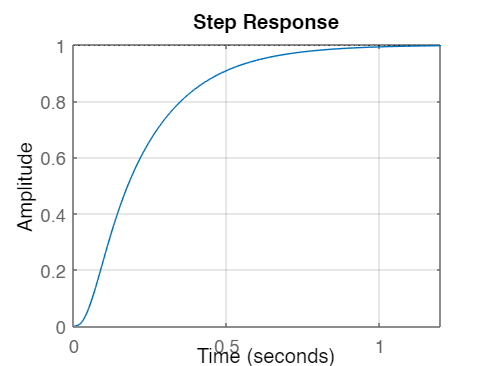

T = feedback(Gnom*K1,1);

step(T), grid

**Disk Margins**

To gauge the robustness of this controller, check the disk margins at the plant inputs and the plant outputs.

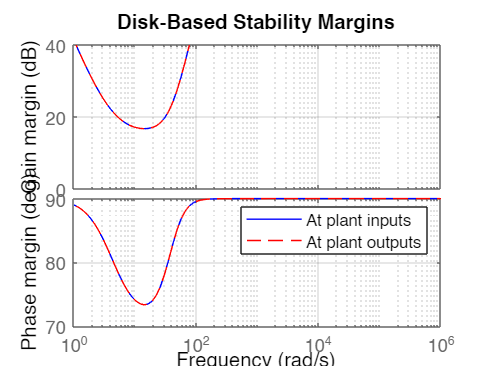

figure
diskmarginplot(K1*Gnom,'b',Gnom*K1,'r--') 
grid
legend('At plant inputs','At plant outputs')

Both are good with near 10 dB gain margin and 50 degrees phase margin. Also check the disk margins when the gain and phase are allowed to vary at both the inputs and outputs of the plant.

MMIO = diskmargin(Gnom,K1)

MMIO = struct with fields:
           GainMargin: [0.4744 2.1081]
          PhaseMargin: [-39.2453 39.2453]
           DiskMargin: 0.7131
           LowerBound: 0.7131
           UpperBound: 0.7145
            Frequency: 6.1686
    WorstPerturbation: [1×1 struct]


The I/O margins are extremely small. This first design also lacks robustness. You can confirm the poor robustness by injecting the smallest destabilizing perturbations returned by `diskmargin` at the plant inputs and outputs. (See [`diskmargin`](https://it.mathworks.com/help/robust/ref/dynamicsystem.diskmargin.html) for further details about the `WorstPerturbation` field of its output structures.)

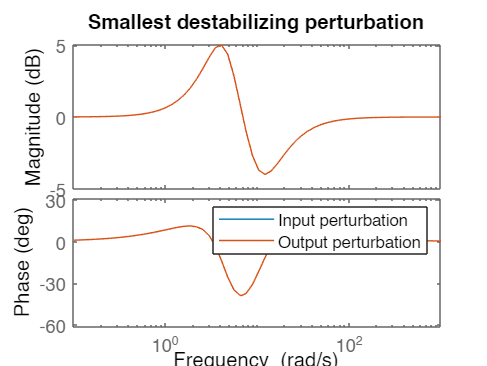

WP = MMIO.WorstPerturbation;
bode(WP.Input,WP.Output)
title('Smallest destabilizing perturbation')
legend('Input perturbation','Output perturbation')

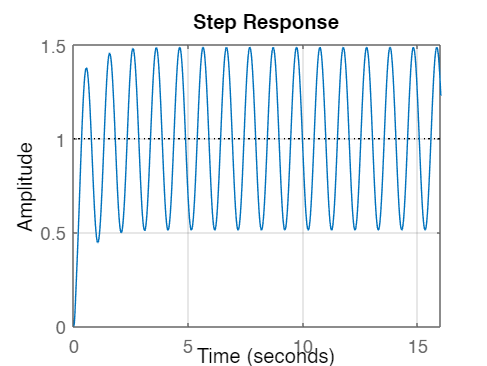


Tpert = feedback(WP.Output*Gnom*WP.Input*K1,1);
step(Tpert)
grid

Augment the plant with the mixed-sensitivity weights and use `musyn` to optimize robust performance for the modeled uncertainty, which includes both the parameter `a` and the gain and phase variations at plant inputs and outputs.

P = augw(Gunc,wS,wKS,wT);
[K2,gam] = musyn(P,1,1);



D-K ITERATION SUMMARY:
-----------------------------------------------------------------
                       Robust performance               Fit order
-----------------------------------------------------------------
  Iter         K Step       Peak MU       D Fit             D
    1             326        5.693        5.746             8
    2           5.635        3.039        3.069            10
    3           2.209        2.168        2.188            10
    4           2.188        2.168        2.188            10
    5           2.188        2.168        2.188            10

Best achieved robust performance: 2.17



The robust performance is close to 1, indicating that the controller is close to robustly meeting the mixed-sensitivity goals. Check the disk margins at the plant I/Os.

MMIO = diskmargin(Gnom,K2)

MMIO = struct with fields:
           GainMargin: [0.4977 2.0093]
          PhaseMargin: [-37.0814 37.0814]
           DiskMargin: 0.6708
           LowerBound: 0.6708
           UpperBound: 0.6721
            Frequency: 9.3774
    WorstPerturbation: [1×1 struct]


The margins are now about 1.6 dB and 25 degrees, much better than before. Compare the step responses with each controller for 25 uncertainty samples.

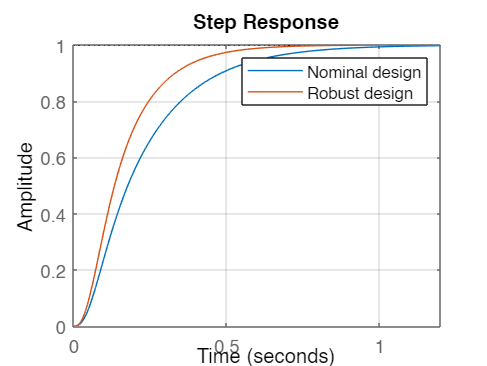

T1 = feedback(Gunc*K1,1);
T2 = feedback(Gunc*K2,1);
rng(0) % for reproducibility

stepplot(T1,T2)
grid
legend('Nominal design','Robust design')

Further compare the sensitivity and complementary sensitivity functions.

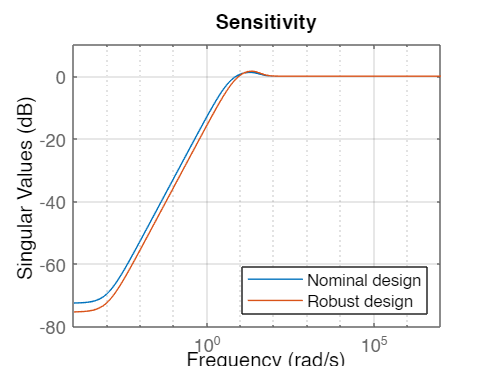

sigma(1-T1,1-T2), grid
title('Sensitivity')
legend('Nominal design','Robust design','location','southeast')

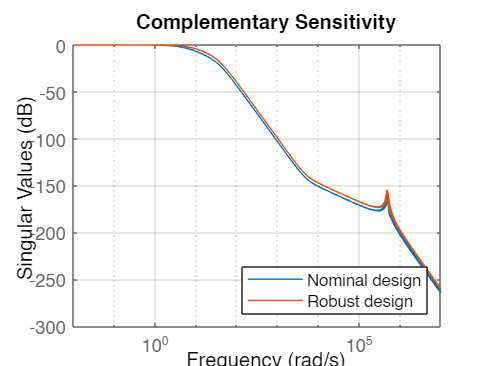


sigma(T1,T2), grid

title('Complementary Sensitivity')
legend('Nominal design','Robust design','location','southeast')